speedPath = ["20220325_1610_RvR_001_speed0.csv",
     "20220325_1611_RvR_001_speed0.csv",
    "20220325_1612_RvR_001_speed0.csv",
    "20220328_1627_RvR_001_speed0.csv",
    "20220328_1629_RvR_001_speed0.csv",
    "20220328_1630_RvR_001_speed0.csv",
    "20220329_1626_RvR_001_speed0.csv",
    %#"20220329_1626_RvR_002_speed0.csv",
    "20220329_1627_RvR_002_speed0.csv",
    %#"20220329_1627_RvR_003_speed0.csv",
    "20220330_1610_RvR_003_speed0.csv",
    "20220330_1612_RvR_002_speed0.csv",
    %#"20220330_1626_RvR_003_speed0.csv",
    %#"20220331_1611_RvR_001_speed0.csv",
    %#"20220331_1612_RvR_003_speed0.csv",
    "20220404_1629_RvR_002_speed0.csv",
    "20220404_1629_RvR_003_speed0.csv",
    "20220404_1630_RvR_002_speed0.csv",
    "20220404_1630_RvR_003_speed0.csv"]

speedPath = 14×1 string array
    "20220325_1610_RvR_001_speed0.csv"
    "20220325_1611_RvR_001_speed0.csv"
    "20220325_1612_RvR_001_speed0.csv"
    "20220328_1627_RvR_001_speed0.csv"
    "20220328_1629_RvR_001_speed0.csv"
    "20220328_1630_RvR_001_speed0.csv"
    "20220329_1626_RvR_001_speed0.csv"
    "20220329_1627_RvR_002_speed0.csv"
    "20220330_1610_RvR_003_speed0.csv"
    "20220330_1612_RvR_002_speed0.csv"
    "20220404_1629_RvR_002_speed0.csv"
    "20220404_1629_RvR_003_speed0.csv"
    "20220404_1630_RvR_002_speed0.csv"
    "20220404_1630_RvR_003_speed0.csv"


RvRpath='/Users/pingchuanma/Desktop/ChenLab_Data/RvR/Current7mice_RvR_raw_data/'

RvRpath = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/Current7mice_RvR_raw_data/'

for i=1:length(speedPath)
    csvfile=convertStringsToChars(speedPath(i));
    speedFilePath=[RvRpath, csvfile];
    [time_of_speed speed_raw]=csvimport(speedFilePath,'columns',[1,2],'noHeader',true);
    time_of_speed(1)=[];
    speed_raw(1)=[];
    

    speed_raw=str2double(speed_raw);
%     speed_raw(find(speed_raw==0))=[];
    eval(['speed_raw_',num2str(i),'=speed_raw;'])

    time_of_speed_seconds=[];
    time_of_speed_string=string;
    reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)];
    reference_time=datetime(reference_time);
    
    for j=1:size(time_of_speed,1)
        hour_num=str2num(time_of_speed{j}(12:13));
        min_num=str2num(time_of_speed{j}(15:16));
        sec_num=str2num(time_of_speed{j}(18:27));
        time_of_speed_seconds(j)=3600*hour_num+60*min_num+sec_num;
    %     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
    %     time_of_speed_string(i)=a;
    %     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
    end


    time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);
    eval(['time_of_speed_',num2str(i),'=time_of_speed_seconds;'])
%     speedBins=-20:1:20;
%     figure
%     hist(speed_raw,speedBins)
%     xticks(-20:1:20)
%     title([csvfile(10:13),' ',csvfile(19:21)])
end

for i=1:length(speedPath)
    eval(['max(time_of_speed_',num2str(i),')'])
    eval(['min(time_of_speed_',num2str(i),')'])
end

ans = 3.5994e+03

ans = 0

ans = 3.5989e+03

ans = 0

ans = 3.5993e+03

ans = 0

ans = 3.5993e+03

ans = 0

ans = 3.5994e+03

ans = 0

ans = 3.5991e+03

ans = 0

ans = 3.5992e+03

ans = 0

ans = 3.5994e+03

ans = 0

ans = 3.5992e+03

ans = 0

ans = 3.5994e+03

ans = 0

ans = 3.5994e+03

ans = 0

ans = 3.5993e+03

ans = 0

ans = 3.5991e+03

ans = 0

ans = 3.5994e+03

ans = 0

time_bins=0:0.25:3600;

for j=1:length(speedPath)
    speed_binned=zeros(1,14400);
    eval(['speed_raw=speed_raw_',num2str(j),';'])
    eval(['time_of_speed=time_of_speed_',num2str(j),';'])

    for i=1:(length(time_bins)-1)
        
        speed_binned(i)=mean(speed_raw(find(time_of_speed>=time_bins(i) & time_of_speed<time_bins(i+1))));
    end

    eval(['speed_binned_',num2str(j),'=speed_binned;'])
end


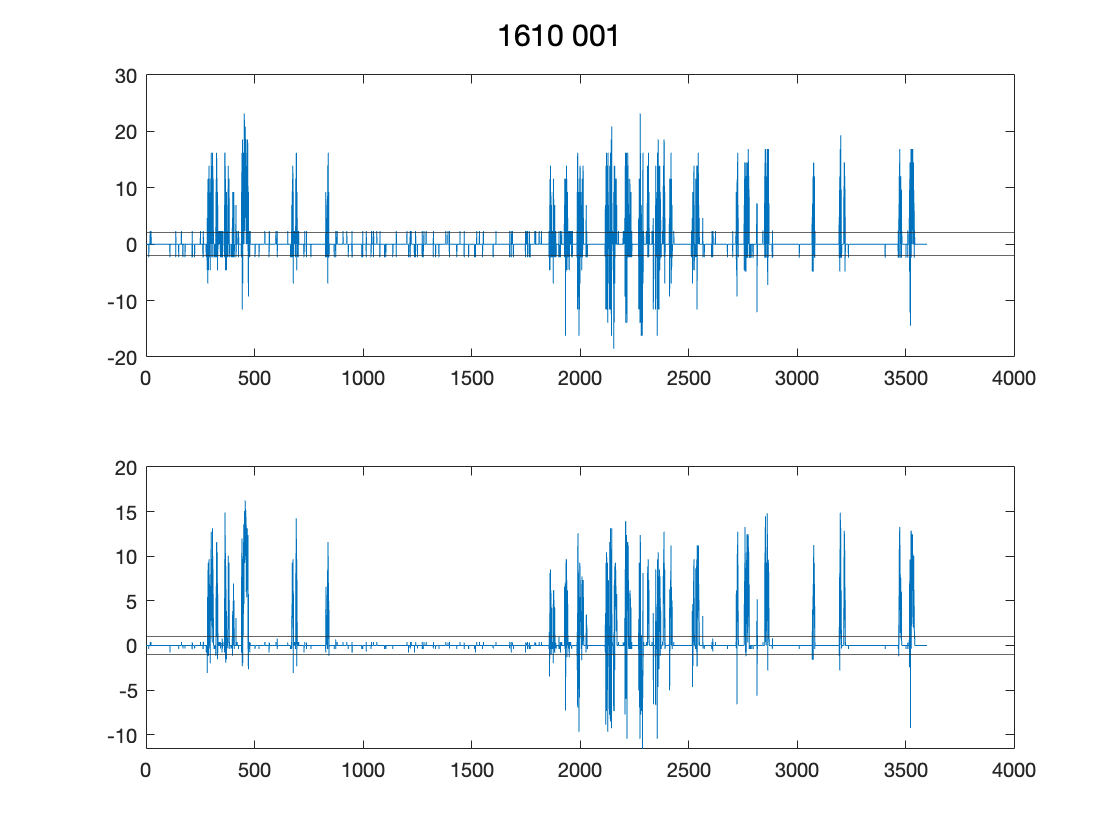

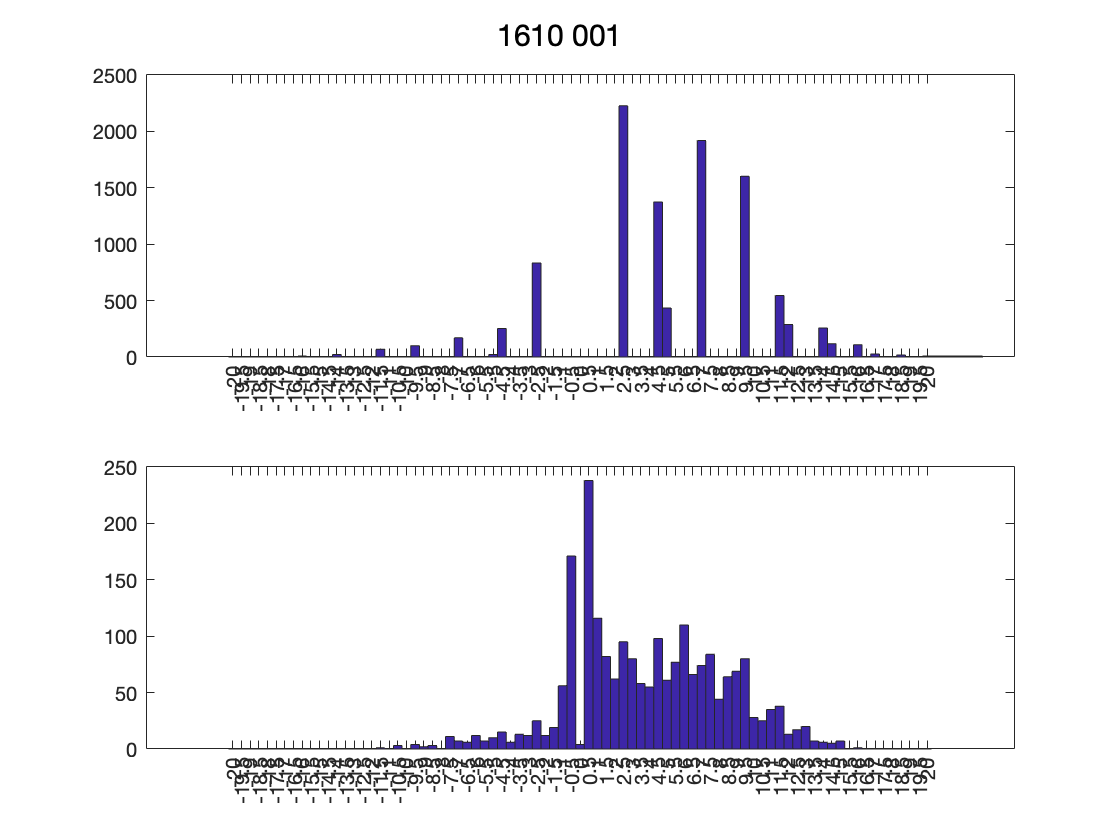

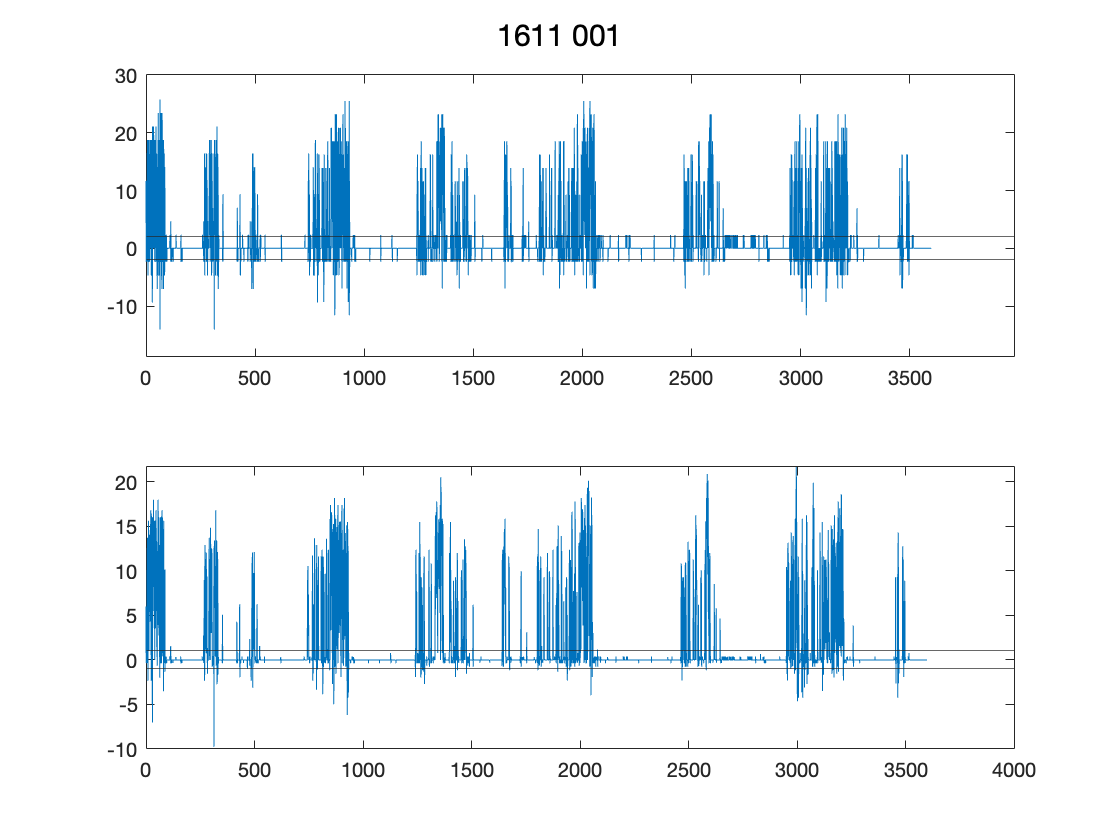

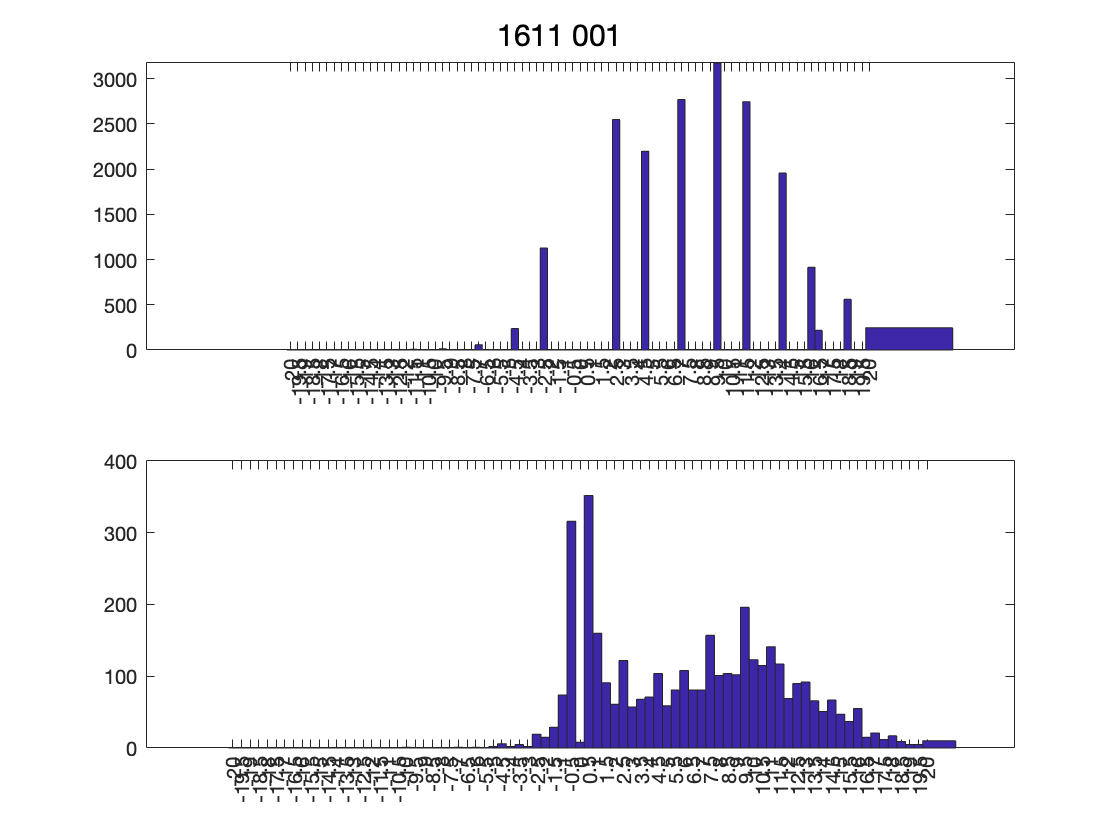

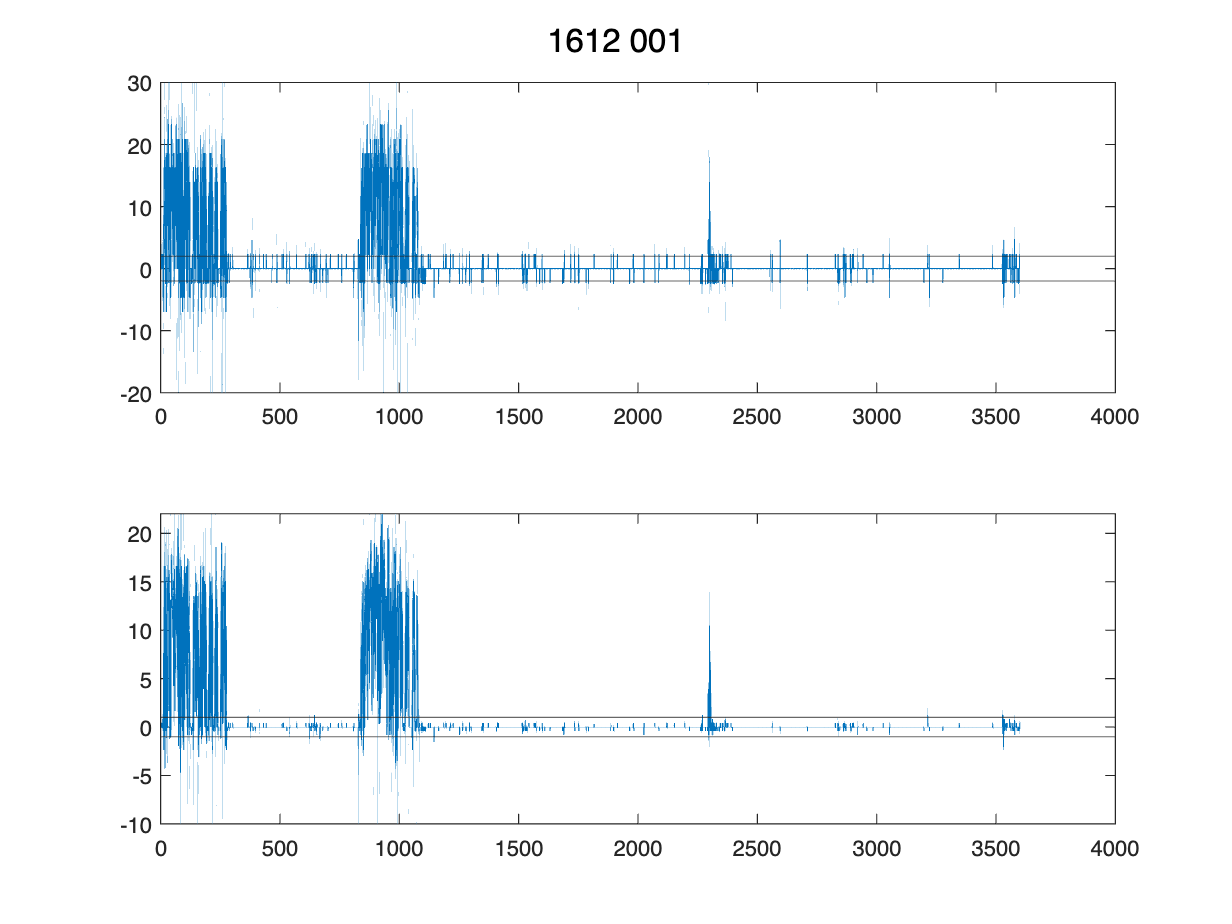

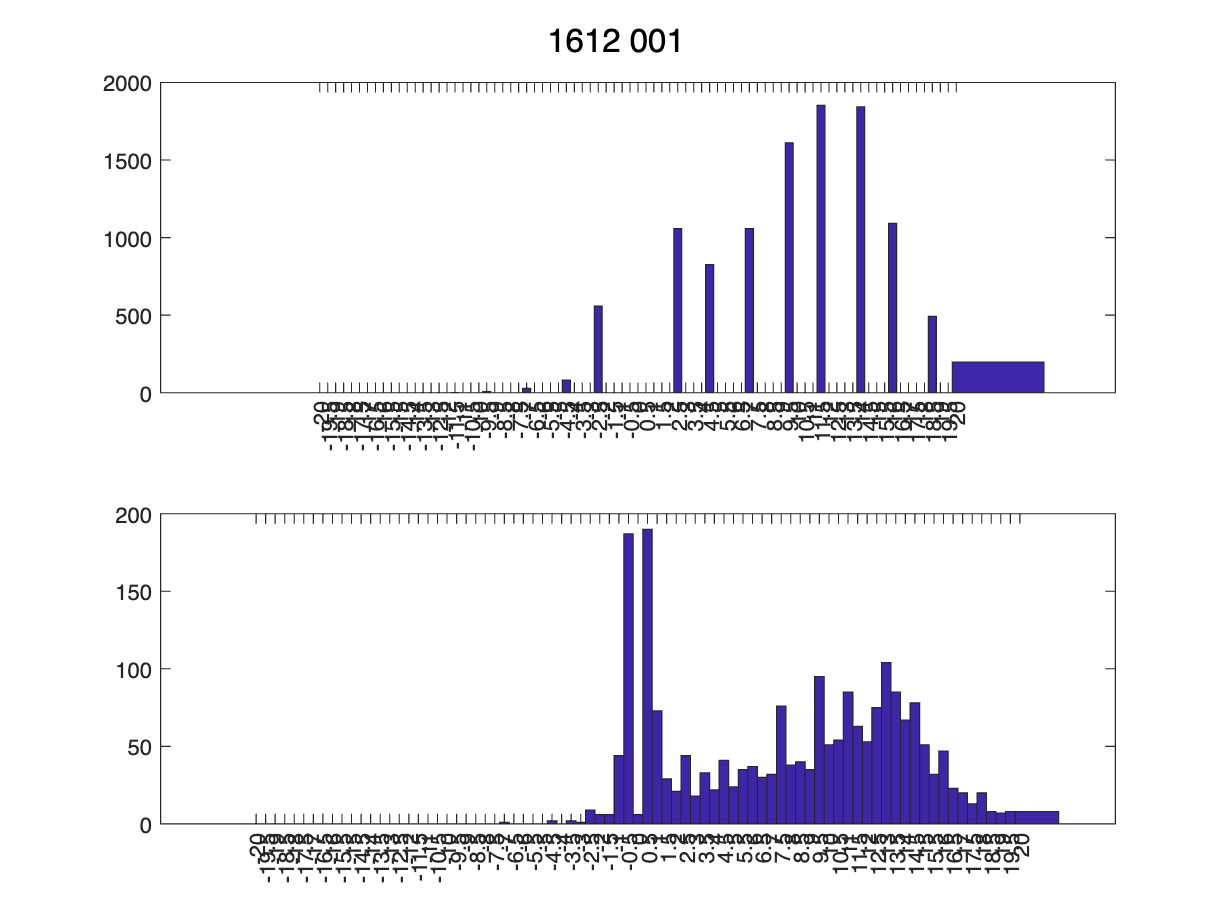

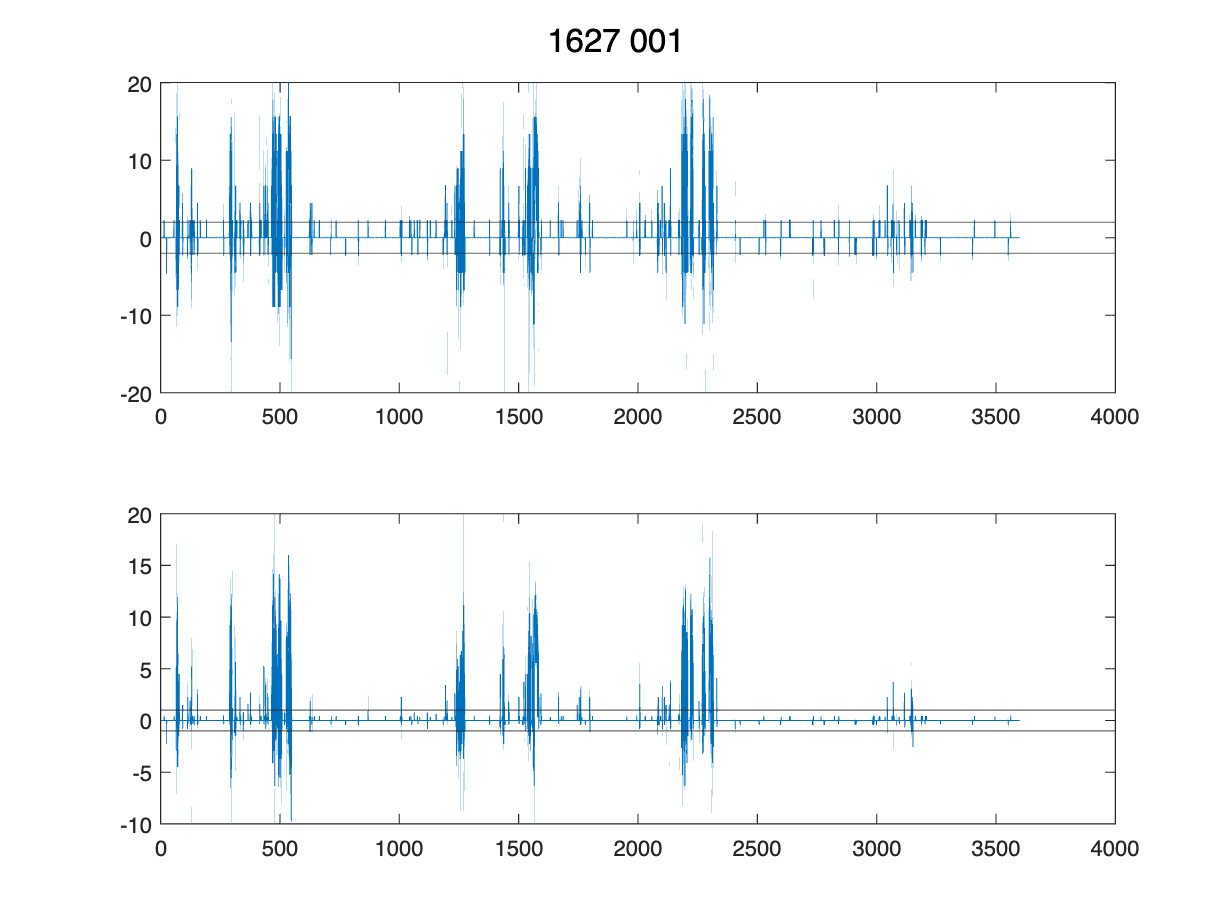

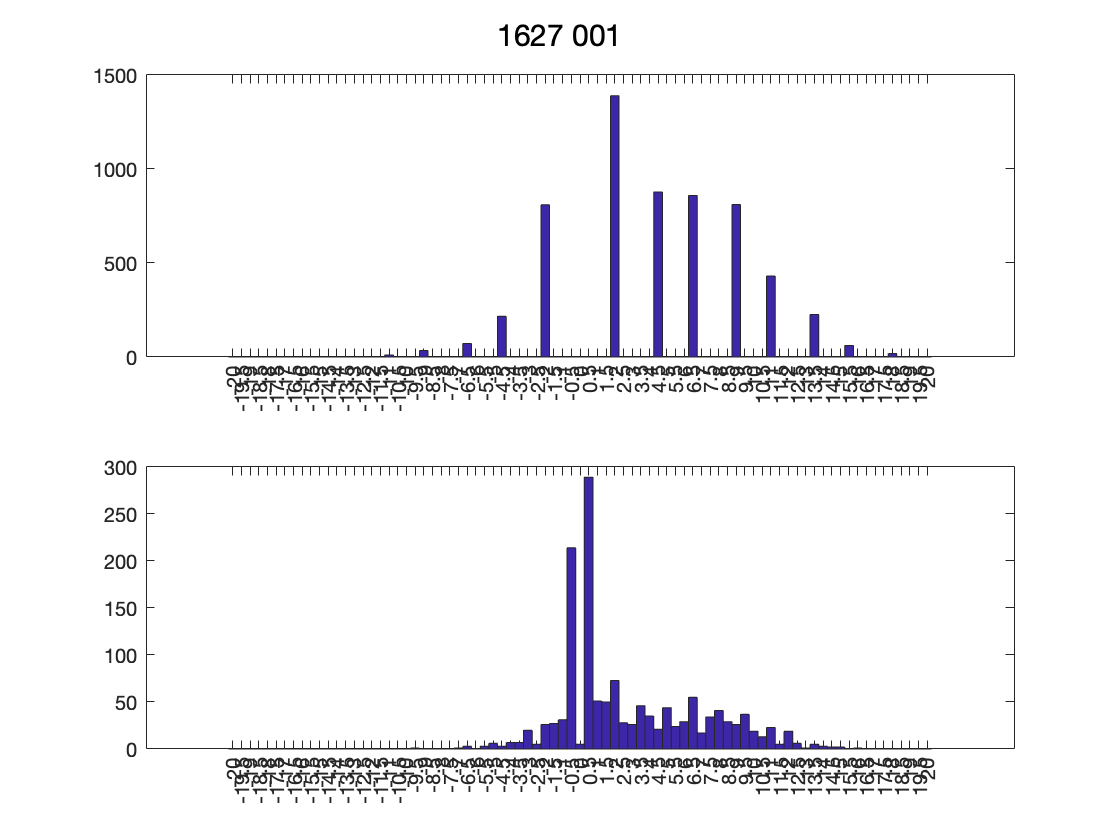

binned_time_plot=(1:1:3600*4)*0.25;
speedBins=-20:0.5:20;

for i=1:length(speedPath)
    csvfile=convertStringsToChars(speedPath(i));
    eval(['speed_raw=speed_raw_',num2str(i),';'])
    eval(['time_of_speed_raw=time_of_speed_',num2str(i),';'])

    eval(['speed_binned=speed_binned_',num2str(i),';'])
    


    figure1=figure;
    subplot(2,1,1)
    plot(time_of_speed_raw,speed_raw)
    yline([-2,2])
    subplot(2,1,2)
    plot(binned_time_plot,speed_binned)
    yline([-1,1])
    sgtitle([csvfile(10:13),' ',csvfile(19:21)])

    speed_raw(find(speed_raw==0))=[];
    speed_binned(find(speed_binned==0))=[];

    figure2=figure;
    subplot(2,1,1)
    hist(speed_raw,speedBins)
    xticks(speedBins)
    subplot(2,1,2)
    hist(speed_binned,speedBins)
    xticks(speedBins)
    sgtitle([csvfile(10:13),' ',csvfile(19:21)])
end

save([RvRpath,'speed_distribution.mat'])

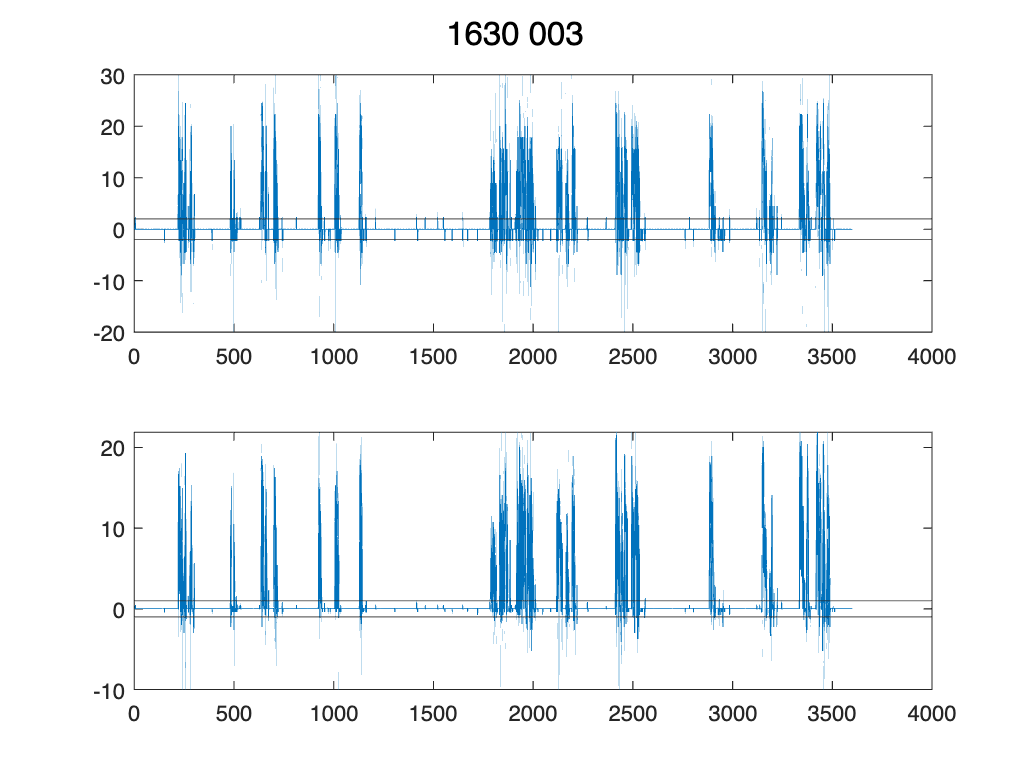

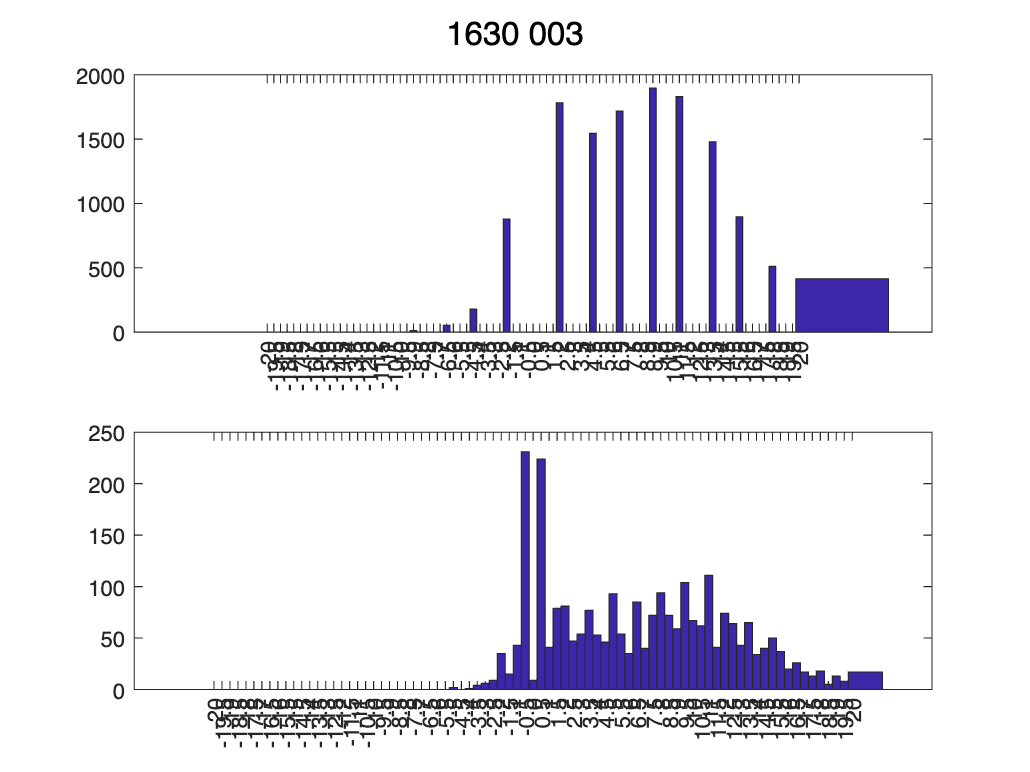

load([RvRpath,'speed_distribution.mat'])

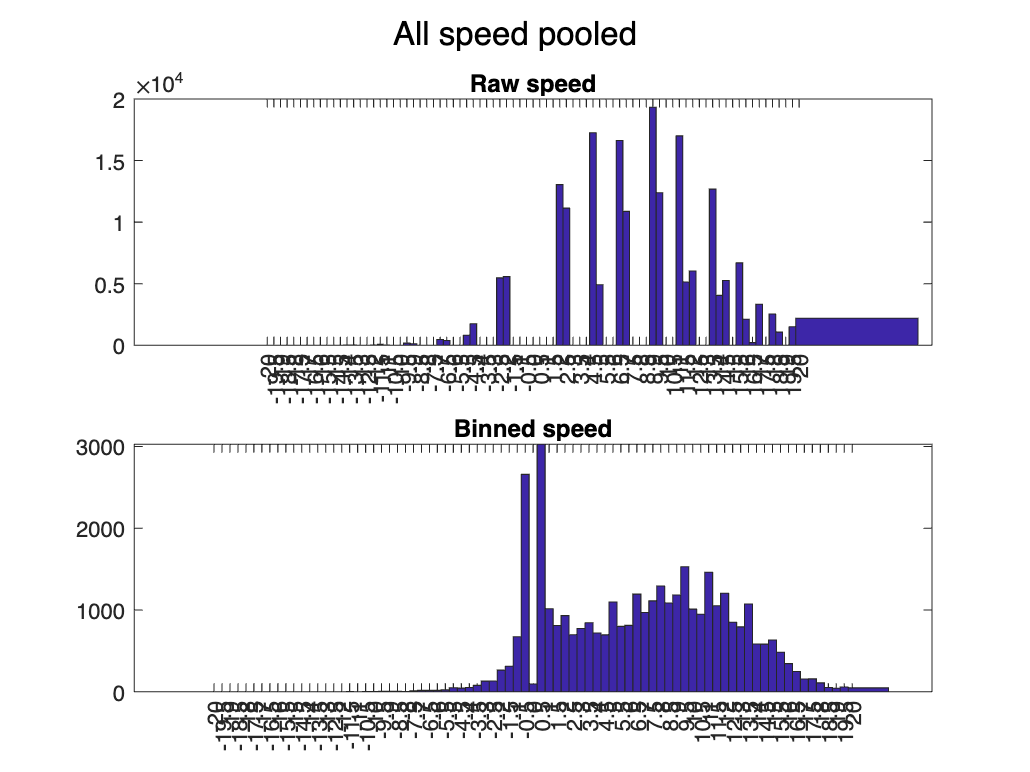

speedBins=-20:0.5:20;
speed_all=[];
speed_binned_all=[];

for i=1:length(speedPath)
    csvfile=convertStringsToChars(speedPath(i));
    eval(['speed_raw=speed_raw_',num2str(i),';'])
    eval(['time_of_speed_raw=time_of_speed_',num2str(i),';'])

    eval(['speed_binned=speed_binned_',num2str(i),';'])

    speed_raw(find(speed_raw==0))=[];
    speed_binned(find(speed_binned==0))=[];

    speed_all=[speed_all;speed_raw];
    speed_binned_all=[speed_binned_all speed_binned];


end

figure;
subplot(2,1,1)
hist(speed_all,speedBins)
xticks(speedBins)
title('Raw speed')
subplot(2,1,2)
hist(speed_binned_all,speedBins)
xticks(speedBins)
title('Binned speed')
sgtitle(['All speed pooled'])